clear; close all;

# kinodynamic motion planning for the given problem

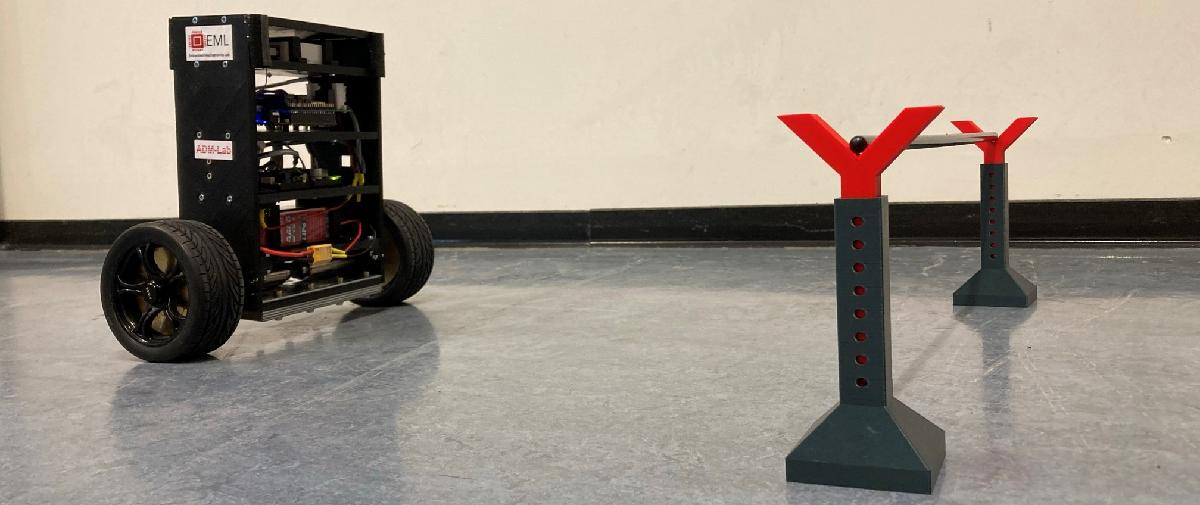

## Setting up the State Space

#### The State Space

% load robot's dynamics
chabo_open_loop_model = load("chabo_ol_dynamics_disc.mat");
chabo_constraints     = chabo_open_loop_model.constraints;
pitch_max             = deg2rad(90);
pitch_min             = deg2rad(-90);
pitch_velocity_max    = 2*pi;
pitch_velocity_min    = -2*pi;
position_max          = 6;
position_min          = -0.25;
position_velocity_max = 2;
position_velocity_min = -2;
constraints_scaling   = 0.75;
flywheel_velocity_max = chabo_constraints.flywheelVelocityMax * constraints_scaling;
flyhweel_velocity_min = - chabo_constraints.flywheelVelocityMax * constraints_scaling;
xmax = [pitch_max; pitch_velocity_max; position_max; position_velocity_max; flywheel_velocity_max];
xmin = [pitch_min; pitch_velocity_min; position_min; position_velocity_min; flyhweel_velocity_min];

% action space constraints. 75% for more conservative approach
umax = [chabo_constraints.tiresTorqueMax; chabo_constraints.flywheelTorqueMax] * 0.75;
umin = [-chabo_constraints.tiresTorqueMax; -chabo_constraints.flywheelTorqueMax] * 0.75;

% handler for state space to config space function
x2y_func = @chabo_x2y;

% set up state space world
statespace = CKinodynamicConfigWorld(xmax, xmin, umax, umin, x2y_func);
% Load our obstacle polygon
load('obstacle.mat');
% Add the obstacle to our world
statespace.addObstacle(obstacle_polygon);

## Setting up the motion planning

### Setting up the local motion planning

% Function to forward simulate Chabo's dynamics to determine state trajectories that result from the planned input trajectories 
% (does not have to use the same model as the Local Motion Planning)
forward_sim_func      = @(x, u)forward_sim(x, u, chabo_open_loop_model.A, chabo_open_loop_model.B);

% Maximum number of samples per LMP between state nodes
Nmax = 50;
% Setup the local motion planning dynamics matrizes
[ANc,RIc] = lmp_precompute_mimo(Nmax, chabo_open_loop_model.A, chabo_open_loop_model.B); % Can be removed
% LMP function
% lmp_func is a function handle which covers all parameters but xI and xG
% returns input trajectory u between two local goals
lmp_func = @(xI, xG)lmp_time_opt_xcon_precomp_mimo(xI, xG,...
                                              umax, umin,...
                                              xmax(5), xmin(5), ...
                                              Nmax,...
                                              ANc, RIc,...
                                              chabo_open_loop_model);

### set up rrt

% Initial state
xI = [0; 0; 0; 0; 0];
% Goal State
xG = [0; 0; 3.5; 0; 0];
% Distance function in state space
distance_func = @chabo_state_distance;
% set RNG-Seed
seed = 8;
rng(seed);
% Max number of iterations / nodes
K = 5000;
% Set goal-check-probability
goal_check_probability = 0.95;

## motion planning

Elapsed time is 8.085043 seconds.


Ntrial = 50

seed = 8

plan_flag = logical
   0


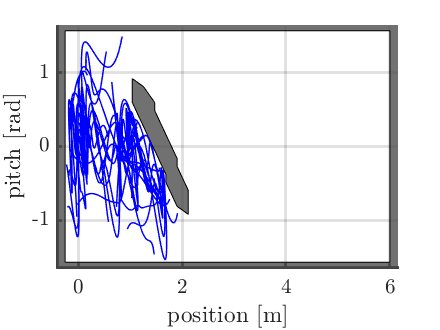

Elapsed time is 10.735804 seconds.


Ntrial = 100

seed = 8

plan_flag = logical
   1


counter = 2

success_counter = 1

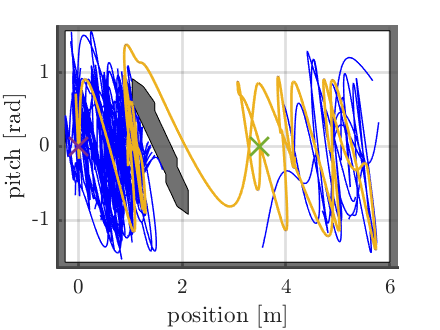

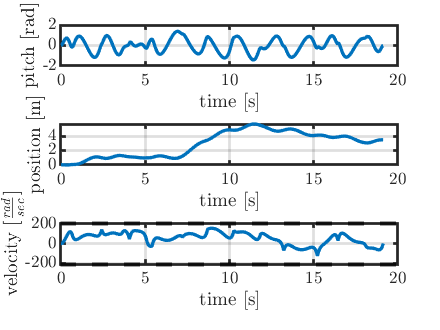

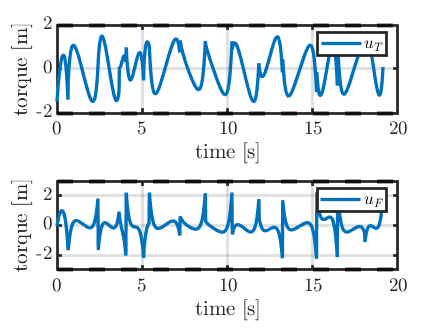

% set up planning loops
nbrOfNLoops     = 10;
counter         = 1;
success_counter = 0;

for k = 1:nbrOfNLoops
        Ntrial = Nmax * k;
        % Setup the local motion planning dynamics matrizes
        [ANc,RIc] = lmp_precompute_mimo(Ntrial, chabo_open_loop_model.A, chabo_open_loop_model.B); % Can be removed
        % LMP function
        % lmp_func is a function handle which covers all parameters but xI and xG
        % returns input trajectory u between two local goals
        lmp_func = @(xI, xG)lmp_time_opt_xcon_precomp_mimo(xI, xG,...
                                              umax, umin,...
                                              xmax, xmin, ...
                                              Ntrial,...
                                              ANc, RIc,...
                                              chabo_open_loop_model);
        tic;
        [plan_flag, tree{counter}, UP_tmp{counter}, XP_tmp{counter}, nodelist] = kinodynamic_planning_mimo(statespace, xI, xG, K, lmp_func, forward_sim_func, x2y_func, distance_func, goal_check_probability);
        toc;
        Ntrial
        seed
        plan_flag
        % Plot the results in C-space
        figure;
        statespace.draw();
        tree{counter}.draw('blue');
        if(plan_flag == 0)
            counter = counter  + 1;
            continue;
        end
        % plot results of successfull kinodynamic planning
        counter
        success_counter     = success_counter + 1
        XP{success_counter} = XP_tmp{counter};
        UP{success_counter} = UP_tmp{counter};
        plotStateTrajectoryInCSpace(XP{success_counter});
        plotConfiguration(xI([1,3]));
        plotConfiguration(xG([1,3]));
        plotStateTrajectoriesOverTime_mimo(XP{success_counter}, UP{success_counter}, chabo_constraints); 
        drawnow;
        counter = counter  + 1;
        if(success_counter >= 1)
            break;
        end
end

### save planned trajectories for later use

time = datetime;
time.Format = 'yyyy-MM-dd''T''HH''h''mm''min';
save(append('05_motion_planning\01_data\00_trajectories\planned_trajectories_', string(time), '.mat'), 'XP', 'UP', 'xI', 'xG', 'statespace', 'xmax', 'xmin', 'umax', 'umin');